p = [1 -7 0 16 25 52];
r = roots(p);

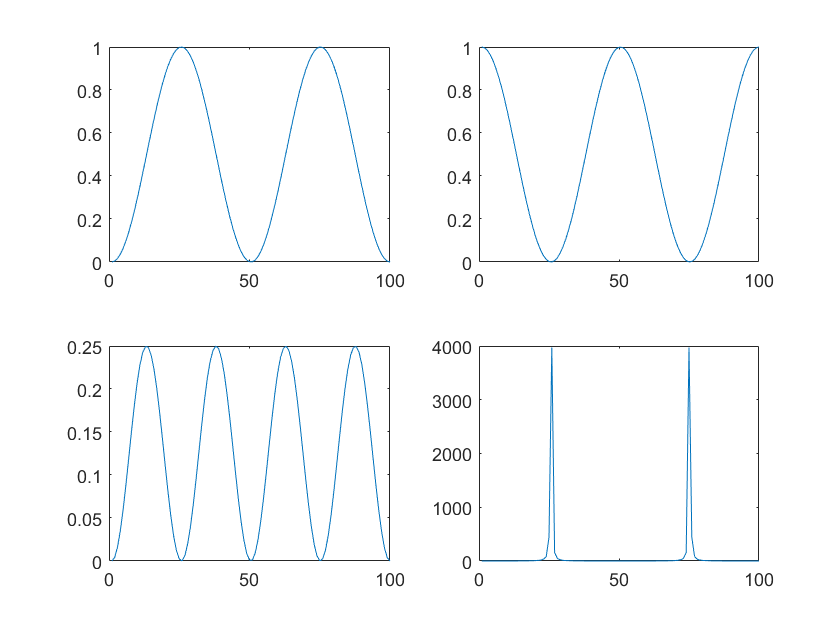

x = linspace(0,2*pi,100);
y = sin(x).^2;
z = cos(x).^2;
w = y.*z;
v = y./z;
subplot(2,2,1);
plot(y);
subplot(2,2,2);
plot(z);
subplot(2,2,3);
plot(w);
subplot(2,2,4);
plot(v);

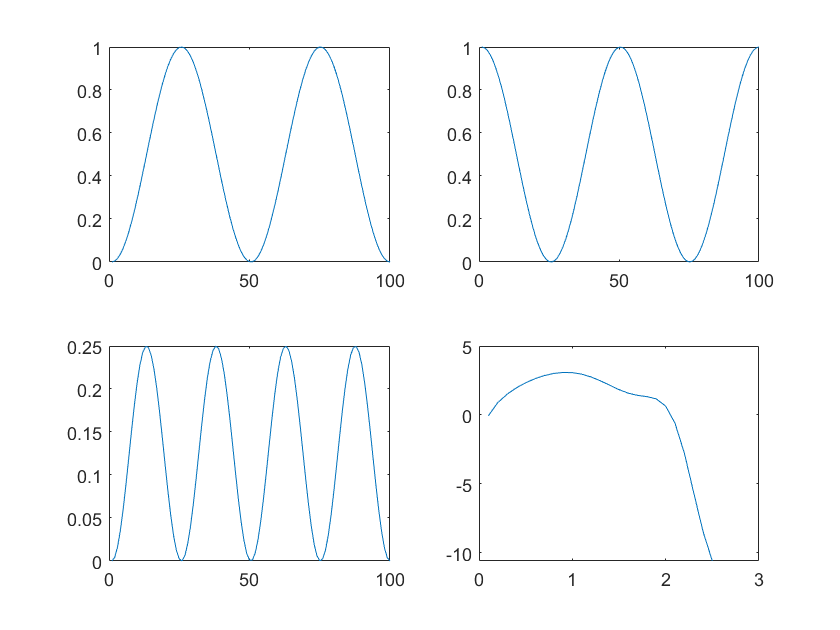

x = 0:0.1:2.5;
y = sin(exp(x))+log(x)-(x-0.5).^4+exp(x.^0.5);
plot(x,y)

sol(1) = fzero(@(x) sin(exp(x))+log(x)-(x-0.5).^4+exp(x.^0.5),0.1);
sol(2) = fzero(@(x) sin(exp(x))+log(x)-(x-0.5)^4+exp(x^0.5),2.5);
final_sol = uniquetol(sol,1e-8);

X = -2:0.1:2;
Y = -2:0.1:2;

[x,y] = meshgrid(X,Y);

z = (x.^2+y.^2-3).*sqrt(x.^2+y.^2)+3/4+...
    sin(8.*sqrt(x.^2+y.^2)).*...
    cos(6.*atan(y./abs(x)))-...
    (3/4).*sin(5.*atan(y./abs(x)));

surf(x,y,z)